## Opg.1

### 1-1 & 1-2

Jeg kan finde pol og nulpunkts diagrammet med at starte med at finde H(z).

nulpunkt: $\left(z+2\right)\left(z-\frac{1+i}{2}\right)\left(z-\frac{1-i}{2}\right)=z^3 +z^2 -\frac{3}{2}z+1$

poler: $z\left(z-\frac{1}{3}\right)\left(z-\frac{2}{3}\right)=z^3 -z^2 +\frac{2}{9}z$

Så kan jeg derfra, lave nogle b og a koefficienter til at plotte pol og nulpunkts diagram.

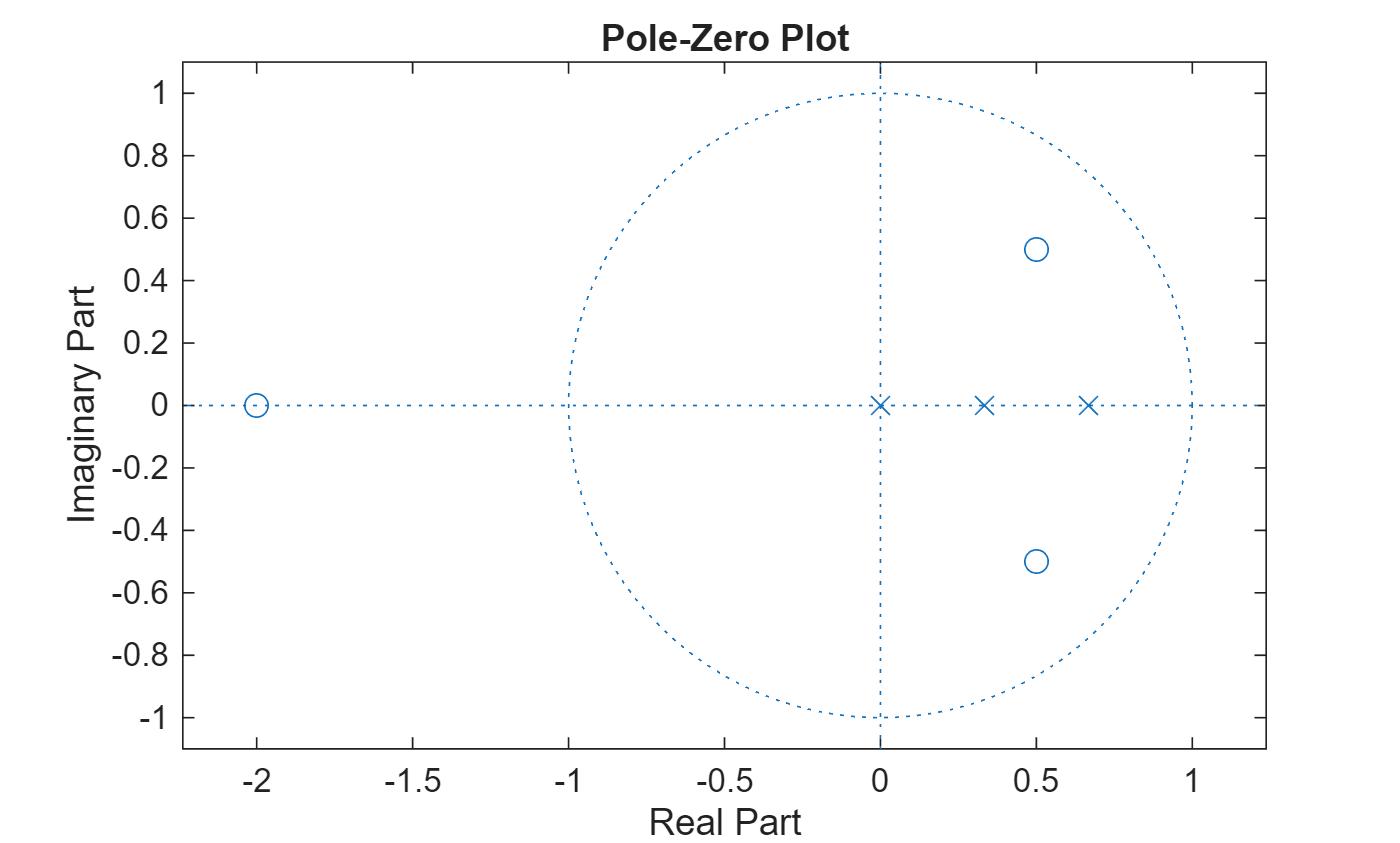

b = [1 1 -(3/2) 1]; a = [1 -1 (2/9)];

zplane(b, a)

Så for H(z)


$$H\left(z\right)=\frac{z^3 +z^2 -\frac{3}{2}z+1}{z^3 -z^2 +\frac{2}{9}z}\cdot \frac{z^{-3} }{z^{-3} }=\frac{{1+z}^{-1} -\frac{3}{2}z^{-2} +z^{-3} }{1-z^{-1} +\frac{2}{9}z^{-2} },\mathrm{ROC}=\left\lbrace z\in \mathbb{C}||z|>\frac{2}{3}\right\rbrace$$


### 1-3

Der ses på pol og nulpunkts digrammet, at systemet er stabilt. Fordi polerne er indenfor enhedscirkelen.

### 1-4


$$x_1 \left\lbrack n\right\rbrack ={\left(\frac{\sqrt{2}}{2}\right)}^n \sin \left(\frac{\pi }{4}n\right)u\left\lbrack n\right\rbrack \overset{\mathcal{Z}}{\longleftrightarrow} \frac{\frac{\sqrt{2}}{2}z^{-1} \sin \left(\frac{\pi }{4}\right)}{1-2z^{-1} \cos \left(\frac{\pi }{4}\right)+{\left(\frac{\sqrt{2}}{2}\right)}^2 z^{-2} }=\frac{\frac{\sqrt{2}}{2}z^{-1} \cdot \frac{\sqrt{2}}{2}}{1-\sqrt{2}z^{-1} \cdot \frac{\sqrt{2}}{2}+\frac{1}{2}z^{-2} }=\frac{\frac{1}{2}z^{-1} }{1-2z^{-1} +\frac{1}{2}z^{-2} }$$


### 1-5


$$X_1 \left(z\right)=\frac{\frac{1}{2}z^{-1} }{1-2z^{-1} +\frac{1}{2}z^{-2} }\cdot \frac{z^2 }{z^2 }=\frac{\frac{1}{2}z}{z^2 -2z+\frac{1}{2}}$$



$$H\left(z\right)=\frac{z^3 +z^2 -\frac{3}{2}z+1}{z^3 -z^2 +\frac{2}{9}z}$$



$$\begin{array}{l}
Y_1 \left(z\right)=H\left(z\right)X_1 \left(z\right)=\frac{z^3 +z^2 -\frac{3}{2}z+1}{z^3 -z^2 +\frac{2}{9}z}\cdot \frac{\frac{1}{2}z}{z^2 -2z+\frac{1}{2}}=\frac{\left(z+2\right)\left(z-\frac{1+i}{2}\right)\left(z-\frac{1-i}{2}\right)}{z\left(z-\frac{1}{3}\right)\left(z-\frac{2}{3}\right)}\cdot \frac{\frac{1}{2}z}{\left(z-1+\frac{\sqrt{2}}{2}\right)\left(z-1-\frac{\sqrt{2}}{2}\right)}=\\
\frac{9\left(-2z^3 -2z^2 +3z-2\right)}{\left(\left(2z-2+\sqrt{2\;}\right)\left(-2z+2+\sqrt{2\;}\right)\left(3z-1\right)\left(3z-2\right)\right)}
\end{array}$$


### 1-7

Definitionen for MP er at alle poler og nulpunkter er indenfor enhedscirkelen. Dvs. at kun nulpunktet -2 bliver først over til AP


$$H_{\mathrm{MP}} \left(z\right)=\frac{\left(z-\frac{1+i}{2}\right)\left(z-\frac{1-i}{2}\right)}{z\left(z-\frac{1}{3}\right)\left(z-\frac{2}{3}\right)},H_{\mathrm{AP}} \left(z\right)=\frac{\left(z+2\right)}{\left(z+\frac{1}{2}\right)}\;\left(\mathrm{hvor}\;\mathrm{zero}=a\Rightarrow \mathrm{pole}=a^* \right)$$


Dvs.


$$H\left(z\right)=H_{\mathrm{MP}} \left(z\right)H_{\mathrm{AP}} \left(z\right)=\frac{\left(z-\frac{1+i}{2}\right)\left(z-\frac{1-i}{2}\right)\cdot \left(z+\frac{1}{2}\right)}{z\left(z-\frac{1}{3}\right)\left(z-\frac{2}{3}\right)}\cdot \frac{\left(z+2\right)}{\left(z+\frac{1}{2}\right)}$$


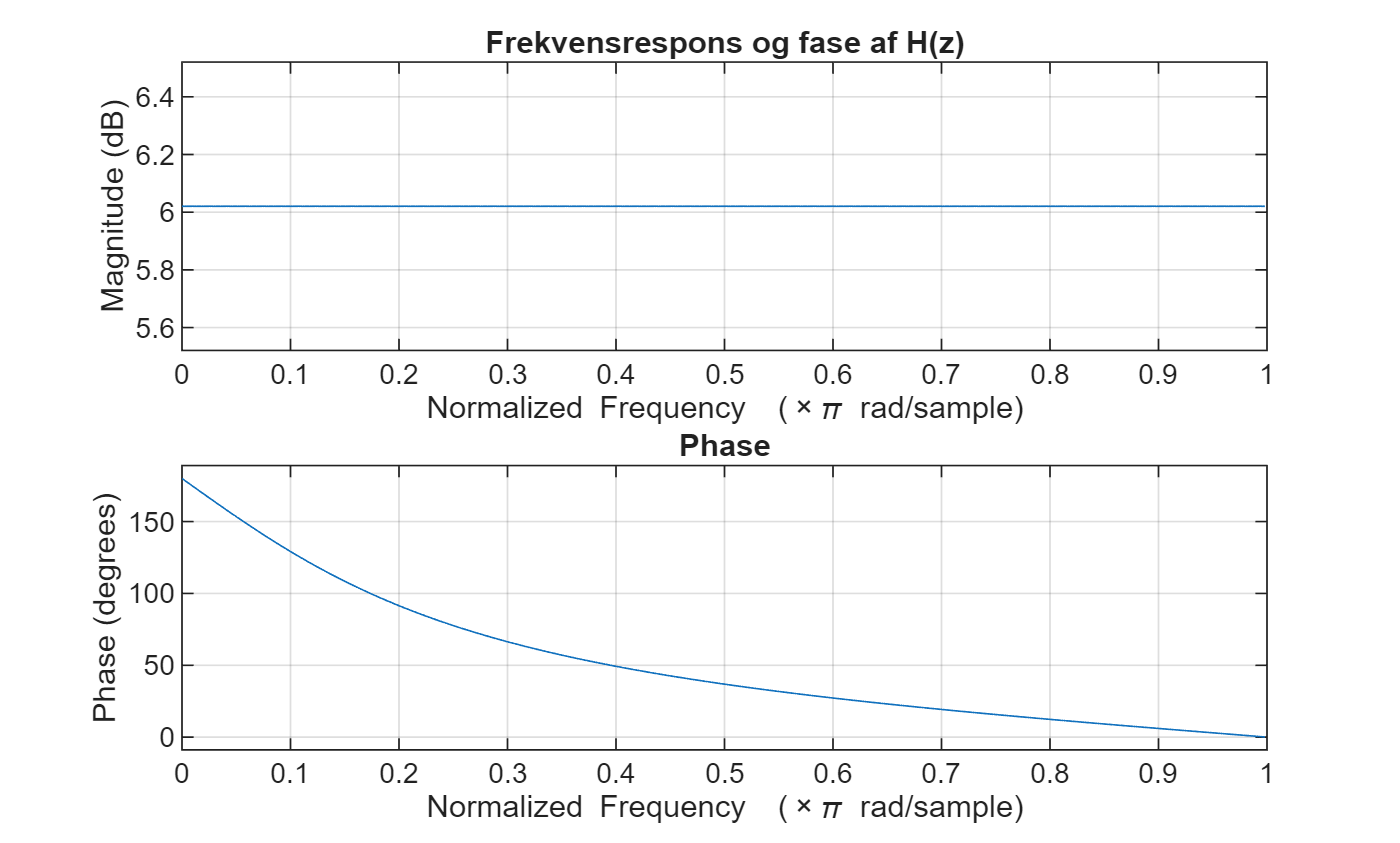

b = [1 -2]; a = [1 -0.5];
figure;
freqz(b, a)
title('Frekvensrespons og fase af H(z)');

AP står for all-pass så ved at der er ingen ændring i frekvens responset som vil sige at intet bliver dæmpet. Ser plottet ud som forvæntet.

## Opg.2

clear; clc;
%Definer b og a koefficienter
b = [0.0940 0.3759 0.5639 0.3759 0.0940]; a = [1 0 0.4860 0 0.0177];

F_s = 1600; A_pdB = 3; f_p = 400;

### 2-1

Overførelses funktionen er skrevet således.

tf(b, a, 1/F_s, 'Variable', 'z^-1')


ans =
 
  0.094 + 0.3759 z^-1 + 0.5639 z^-2 + 0.3759 z^-3 + 0.094 z^-4
  ------------------------------------------------------------
                  1 + 0.486 z^-2 + 0.0177 z^-4
 
Sample time: 0.000625 seconds
Discrete-time transfer function.


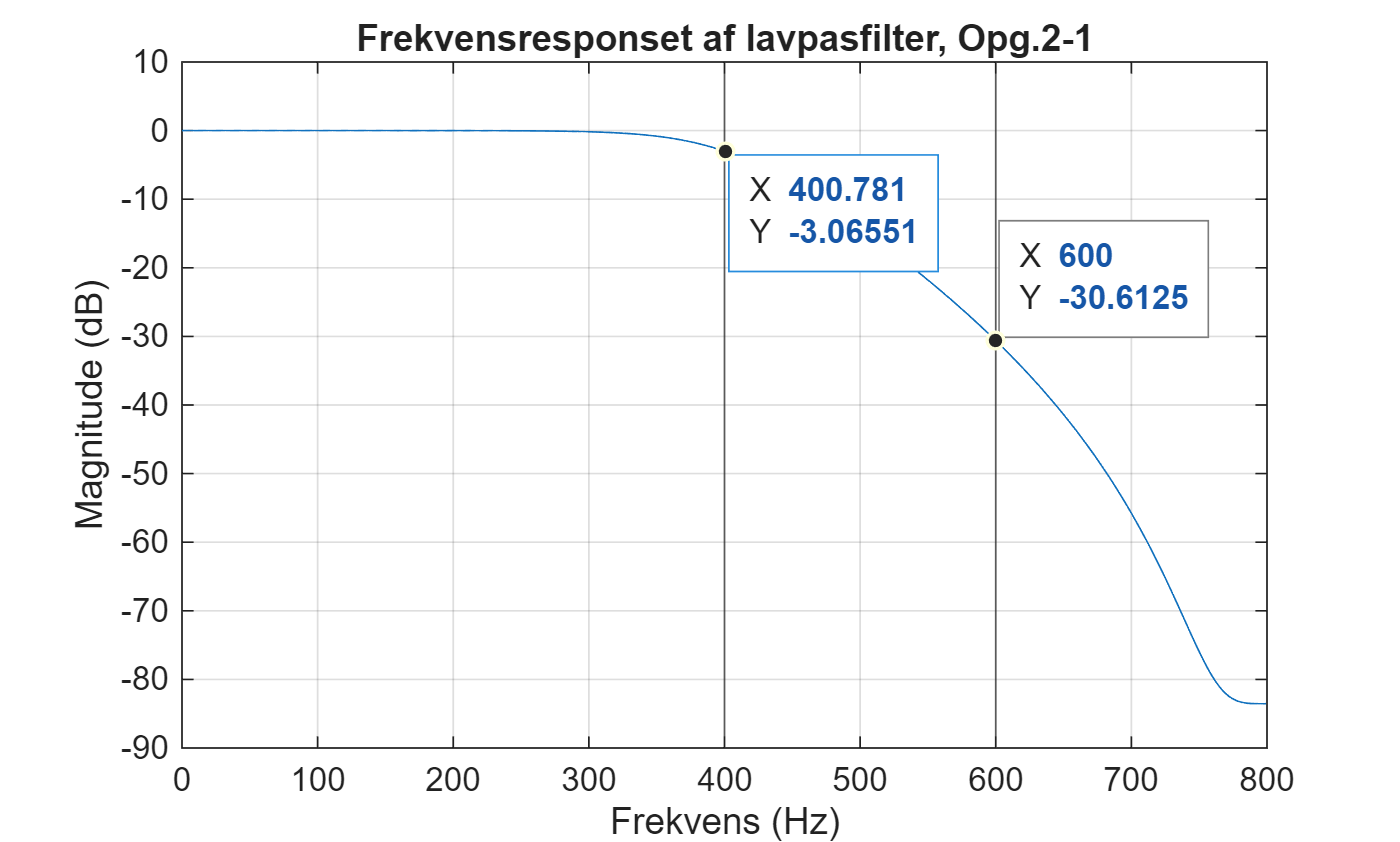


[h, f] = freqz(b, a, 1024, F_s);
figure;
plot(f, 20*log10(abs(h)));
xlabel('Frekvens (Hz)');
ylabel('Magnitude (dB)');
xline([400 600]);
title('Frekvensresponset af lavpasfilter, Opg.2-1');
grid on;

ax = gca;
chart = ax.Children(3);
datatip(chart,600,-30.61);
datatip(chart,400.8,-3.066);

Der ses på plottet, at ved 400Hz er dæmpningen 3dB og ved 600Hz er det 30dB.

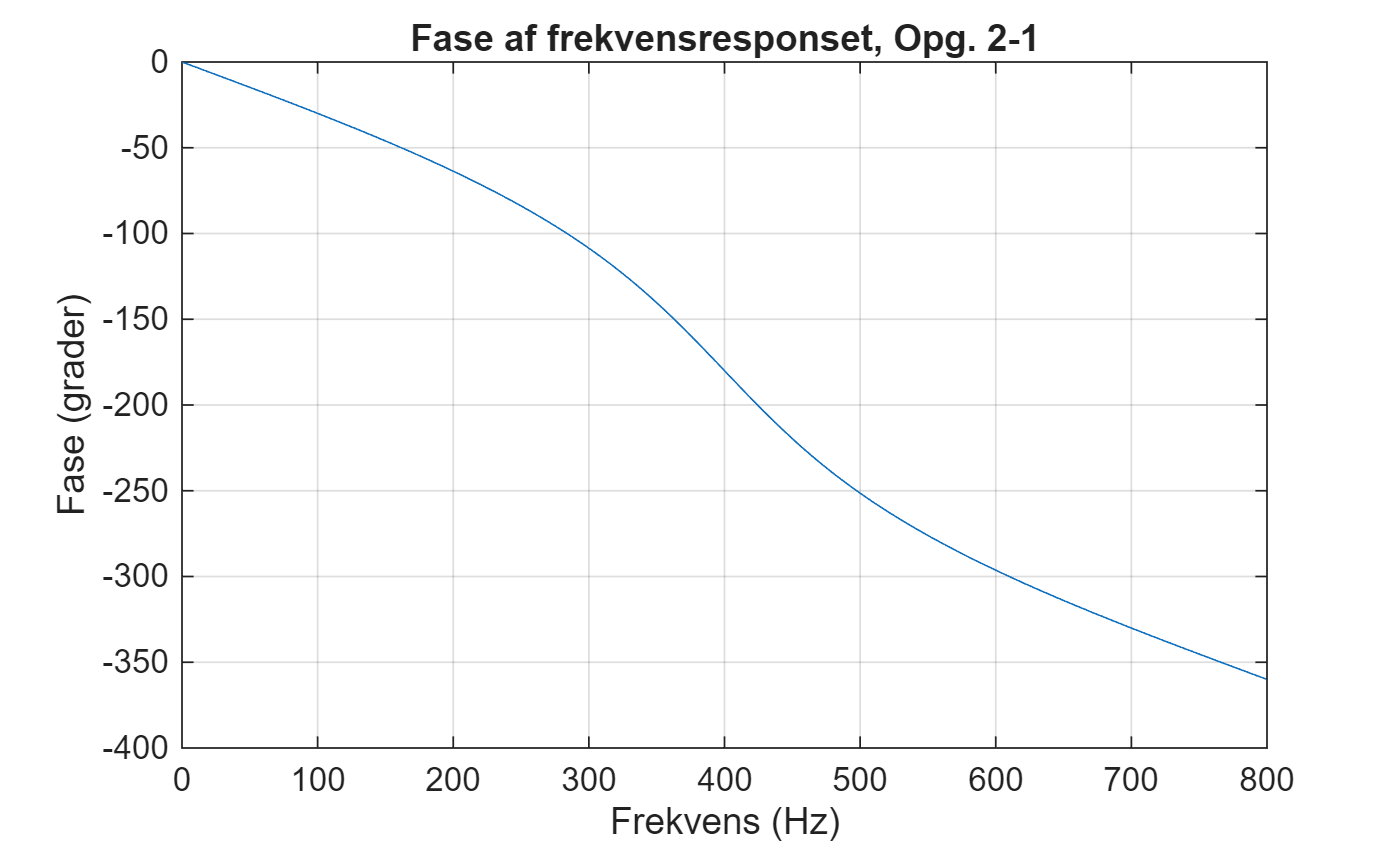

figure;
plot(f, rad2deg(unwrap(angle(h))));
xlabel('Frekvens (Hz)');
ylabel('Fase (grader)');
title('Fase af frekvensresponset, Opg. 2-1');
grid on;

Der ses, at fasen er ikke linær, dette er også forventet fordi filteret er et IIR filter.

### 2-2

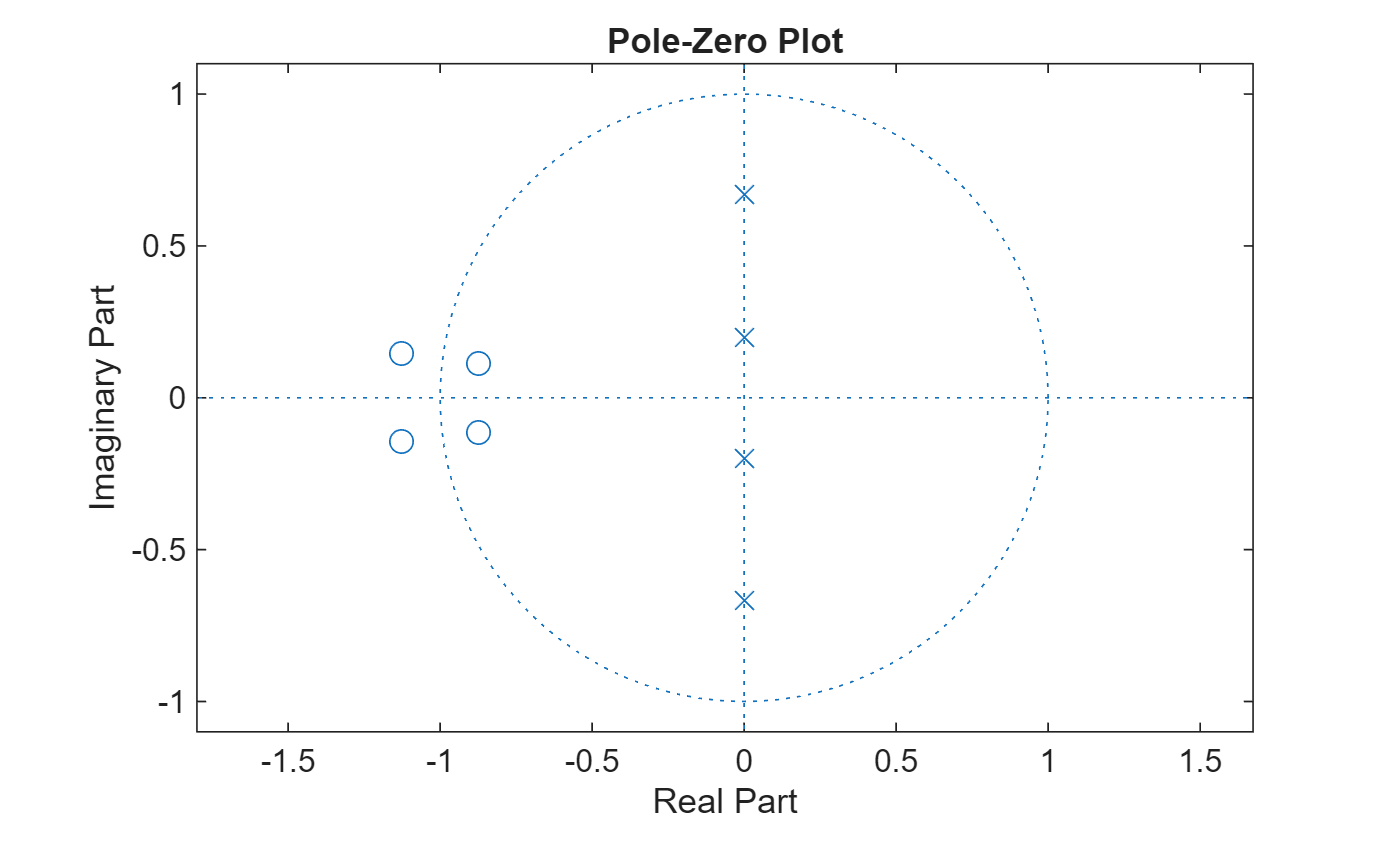

zplane(b, a);

Filteret er stabilt, fordi polerne er indenfor enhedscirkelen.

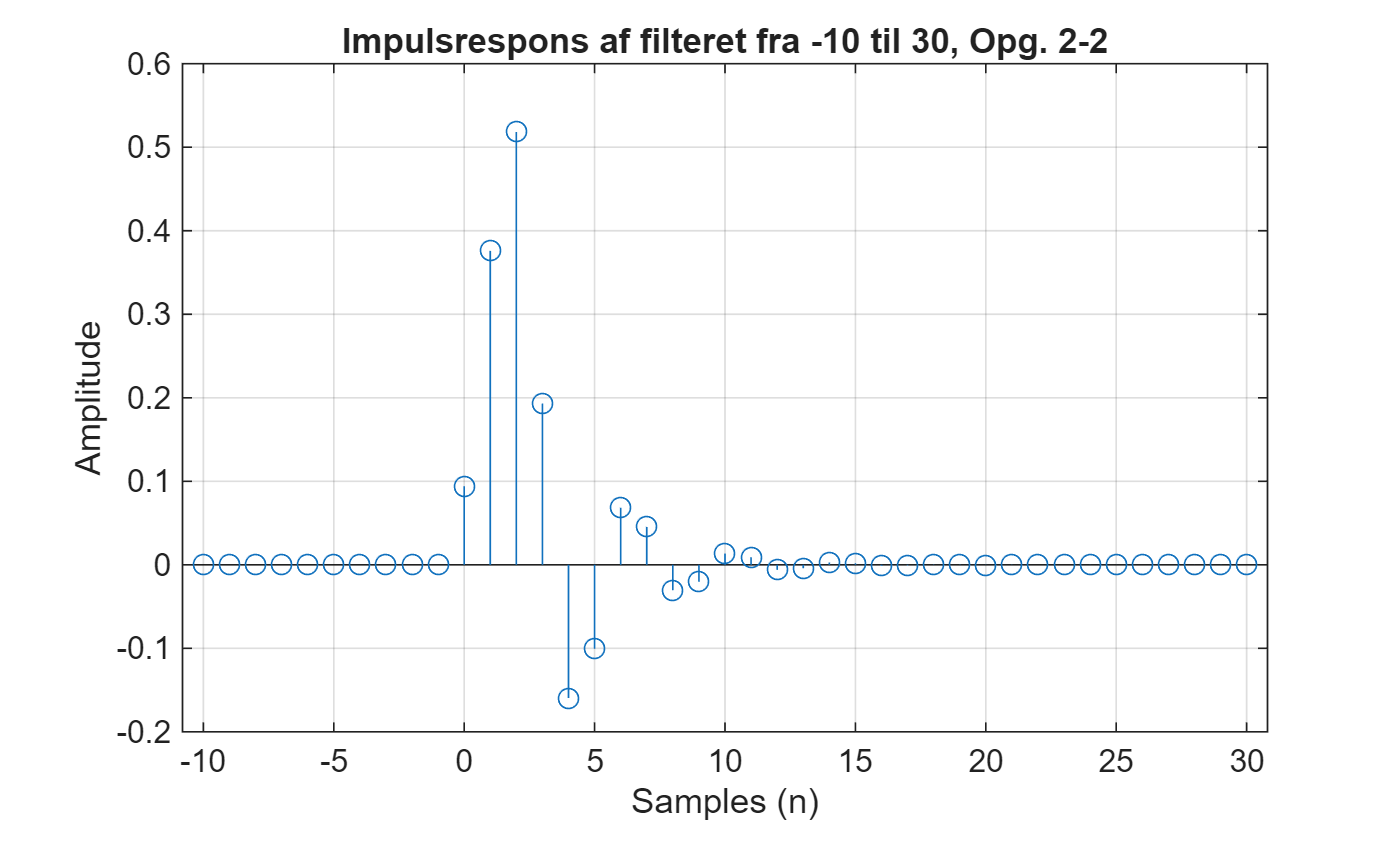

%Jeg laver en unit impulse vektor med størrelsen af d.
d = zeros(1, 41);
d(10+1) = 1;
n = -10:30;
h = filter(b, a, d);

figure;
stem(n, h);
xlabel('Samples (n)');
ylabel('Amplitude');
title('Impulsrespons af filteret fra -10 til 30, Opg. 2-2');
grid on;

### 2-3

F_1 = 100; F_2 = 300; F_3 = 600; A_1 = 1; A_2 = 2; A_3 = 3; N = 2^14;

For at aliasering skal undgås, kan et signal ikke være højere end nyquist frekvensen af $\frac{F_s }{2}$

Og for en sampling frekvens af 1600Hz, er det 800Hz.

Dvs. Der kan ikke være noget signal højere end 800Hz uden aliasering.

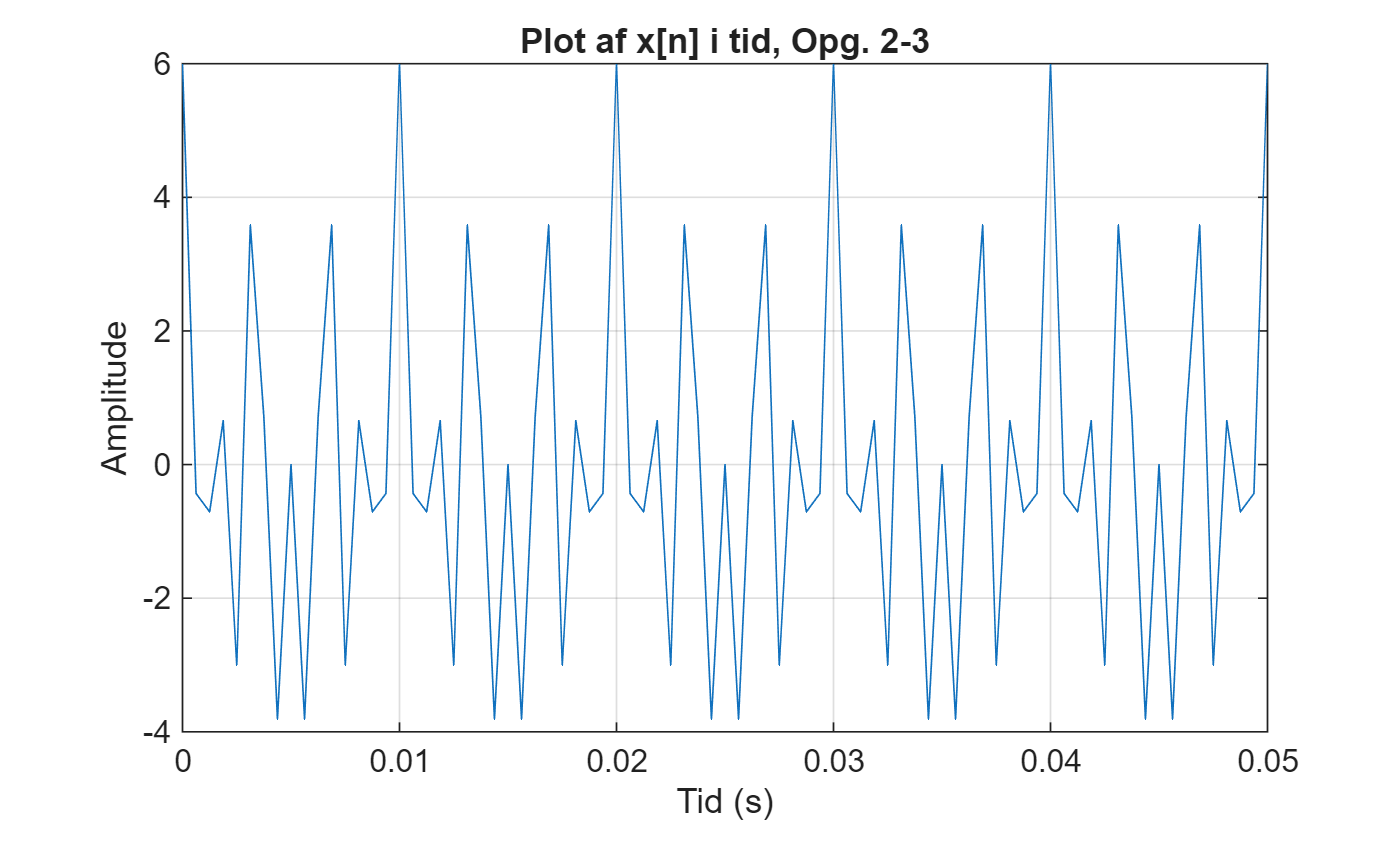

%Jeg bruger min time_vec funktion til at lave tids vektoren.
t = time_vec(F_s, N);

x_n = A_1*cos(2*pi*F_1*t)+A_2*cos(2*pi*F_2*t)+A_3*cos(2*pi*F_3*t);

figure;
plot(t, x_n);
xlim([0 0.05]);
xlabel('Tid (s)');
ylabel('Amplitude');
title('Plot af x[n] i tid, Opg. 2-3');
grid on;

### 2-4

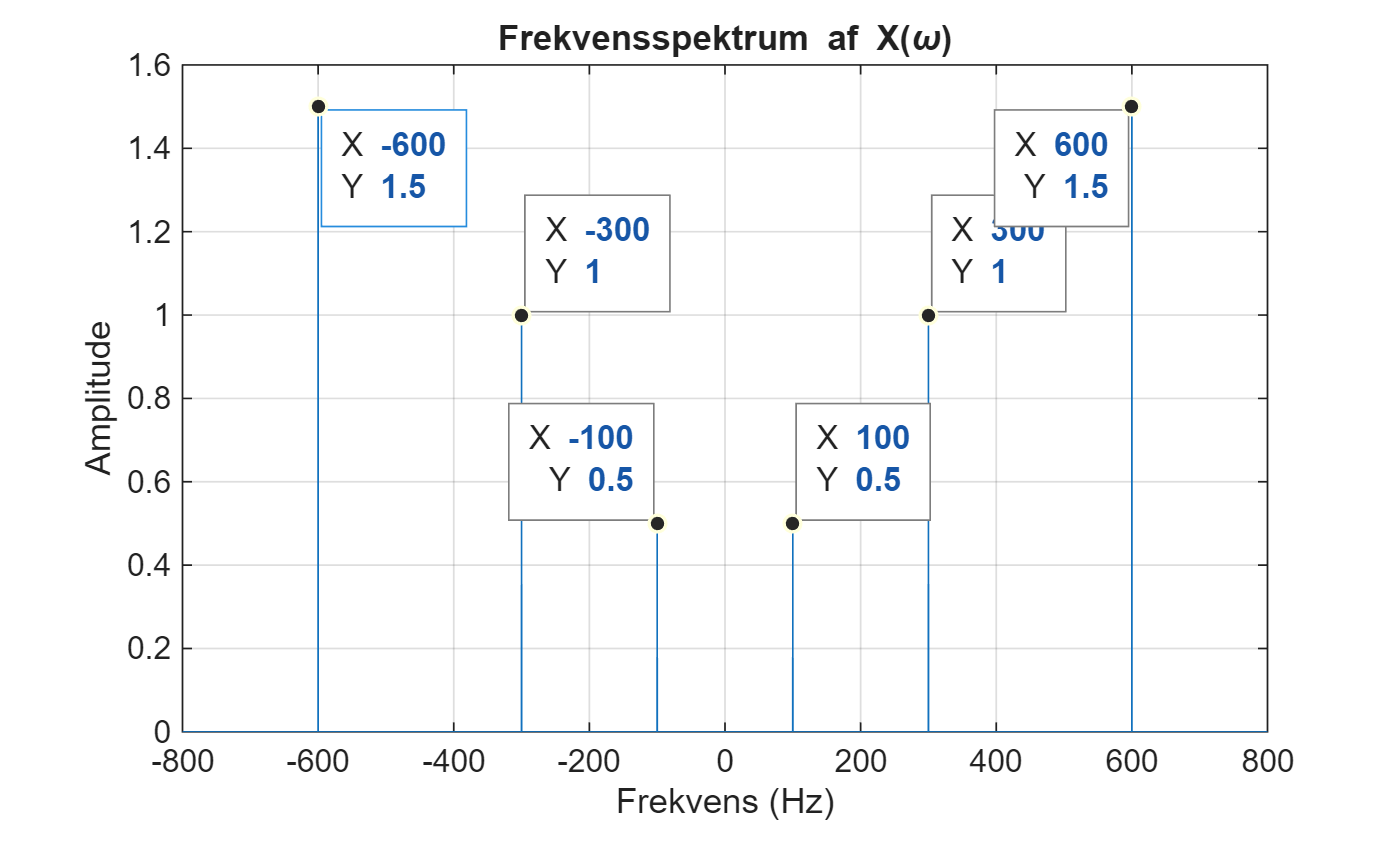

X_z = fftshift(fft(x_n));
f_v = frequency_vec(F_s, N);

figure;
plot(f_v, abs(X_z)/length(X_z));
xlabel('Frekvens (Hz)');
ylabel('Amplitude');
title('Frekvensspektrum af X(\omega)');
grid on;

ax2 = gca;
chart2 = ax2.Children(1);
datatip(chart2,100,0.5);
datatip(chart2,-100,0.5,"Location","northwest");
datatip(chart2,-300,1);
datatip(chart2,300,1);
datatip(chart2,600,1.5);
datatip(chart2,-600,1.5);

Frekvenskomponenterne stemmer overens, men amplituderne er mindre end forventet. Det ville være pga. de er blandet sammen, hvor der bliver skapt noget 'interference' mellem de tre signaler.

### 2-5

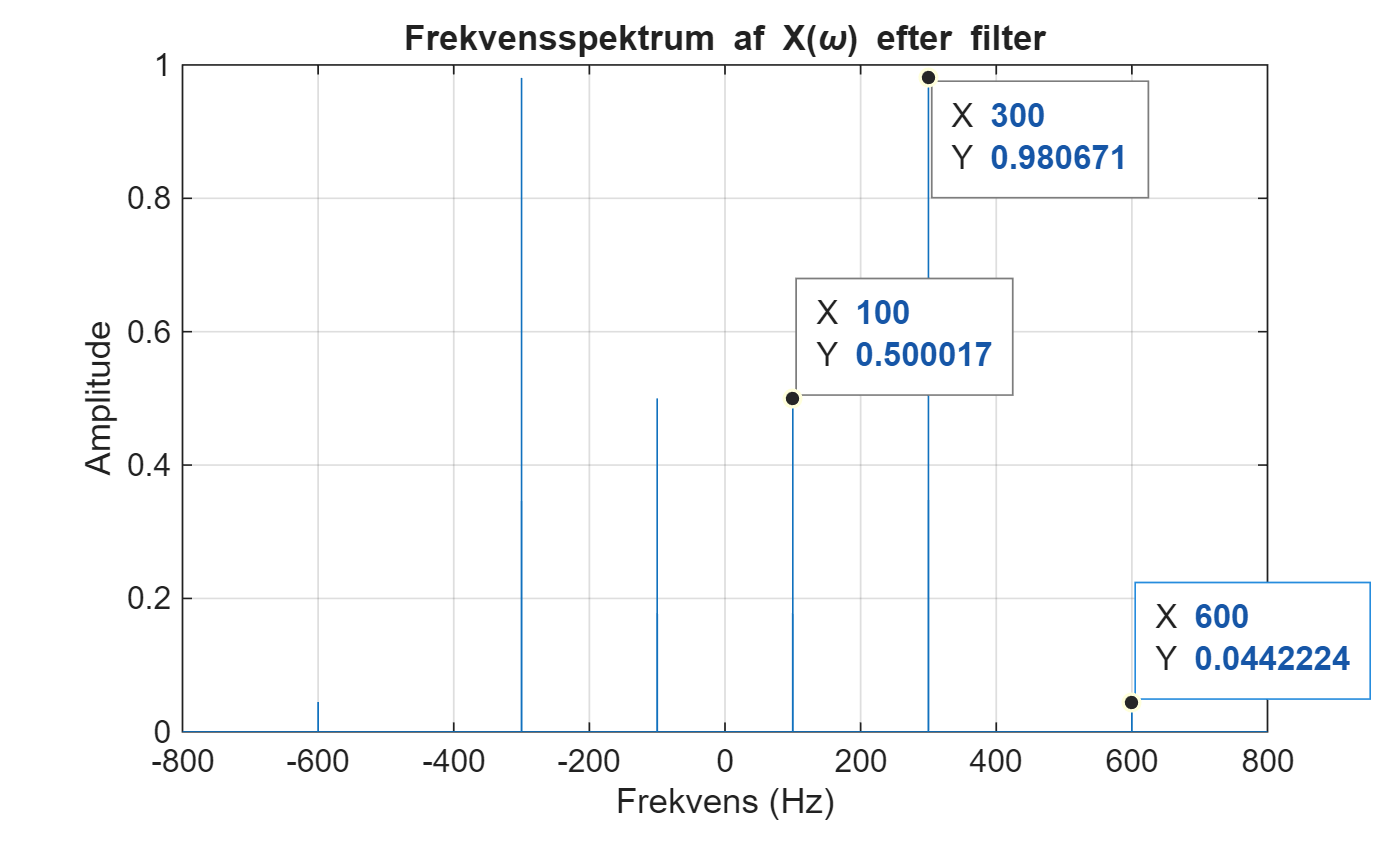

x_filter = filter(b, a, x_n);

X_Filter = fftshift(fft(x_filter));

figure;
plot(f_v, abs(X_Filter)/length(X_Filter));
xlabel('Frekvens (Hz)');
ylabel('Amplitude');
title('Frekvensspektrum af X(\omega) efter filter');
grid on;

ax3 = gca;
chart3 = ax3.Children(1);
datatip(chart3,100,0.5);
datatip(chart3,300,0.9807);
datatip(chart3,600,0.04422,"Location","northeast");

Der ses ved plottet, at amplituderne for 100Hz, 300Hz og 600Hz. Er 0.5, 0.98 og 0.04.

A_600_dB = 20*log10(0.0442224)

A_600_dB = -27.0872

Det passer også meget med hvad vi fik med frekvensresponset af filteret. Hvor her har vi en dæmpning på 27dB, så har filteret en dæmpning på 30dB ved 600Hz.

## Opg.3

clear; clc;
f_p = 1750; f_s = 1250; A_sdB = 20; F_s = 5e3;
%Cutoff frekvens
F_c = (f_s + f_p)/2

F_c = 1500

%omega_c
omega_c = (2*pi*F_c)/F_s

omega_c = 1.8850

%Skarpheden
F_sharp = abs(f_s-f_p)/F_s

F_sharp = 0.1000

Siden der ønskes en dæmpning på 20dB, så er et rektangulært vindue passende.

For et rektangulært vindue er formelen: $N_{\textrm{taps}} =\frac{0\ldotp 9}{\Delta F_{\textrm{sharpness}} }$

N_taps = 0.9/F_sharp

N_taps = 9

### 3-2

%Jeg bruger min MK funktion til at finde M og K værdierne.
[M, K] = MK_values(N_taps);
n = -K:K

n =     -4    -3    -2    -1     0     1     2     3     4


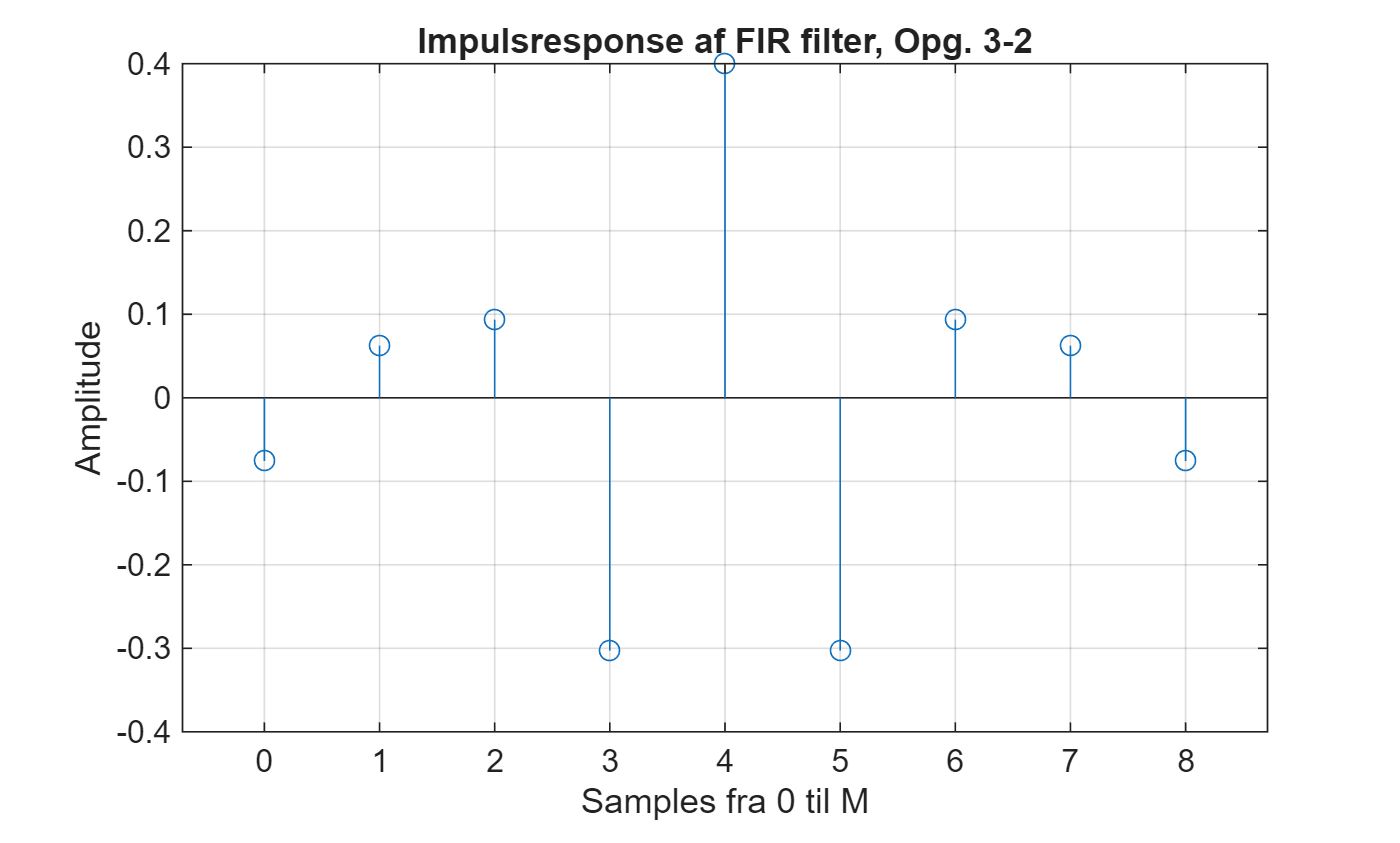

%Her bruger jeg min FIR_fourier funktion til at beregne impulsresponsen.
h = FIR_fourier("HP", n, omega_c);

%Siden rektangulær vindue er brugt, så bliver impulsresponsen ganget med 1,
%så det er det samme som før.
figure;
stem(0:M, h)
xlabel('Samples fra 0 til M');
ylabel('Amplitude');
title('Impulsresponse af FIR filter, Opg. 3-2');
grid on;

### 3-3

tf(h, 1, F_s)


ans =
 
  -0.07568 z^8 + 0.06237 z^7 + 0.09355 z^6 - 0.3027 z^5 + 0.4 z^4 - 0.3027 z^3 + 0.09355 z^2 + 0.06237 z - 0.07568
 
Sample time: 5000 seconds
Discrete-time transfer function.


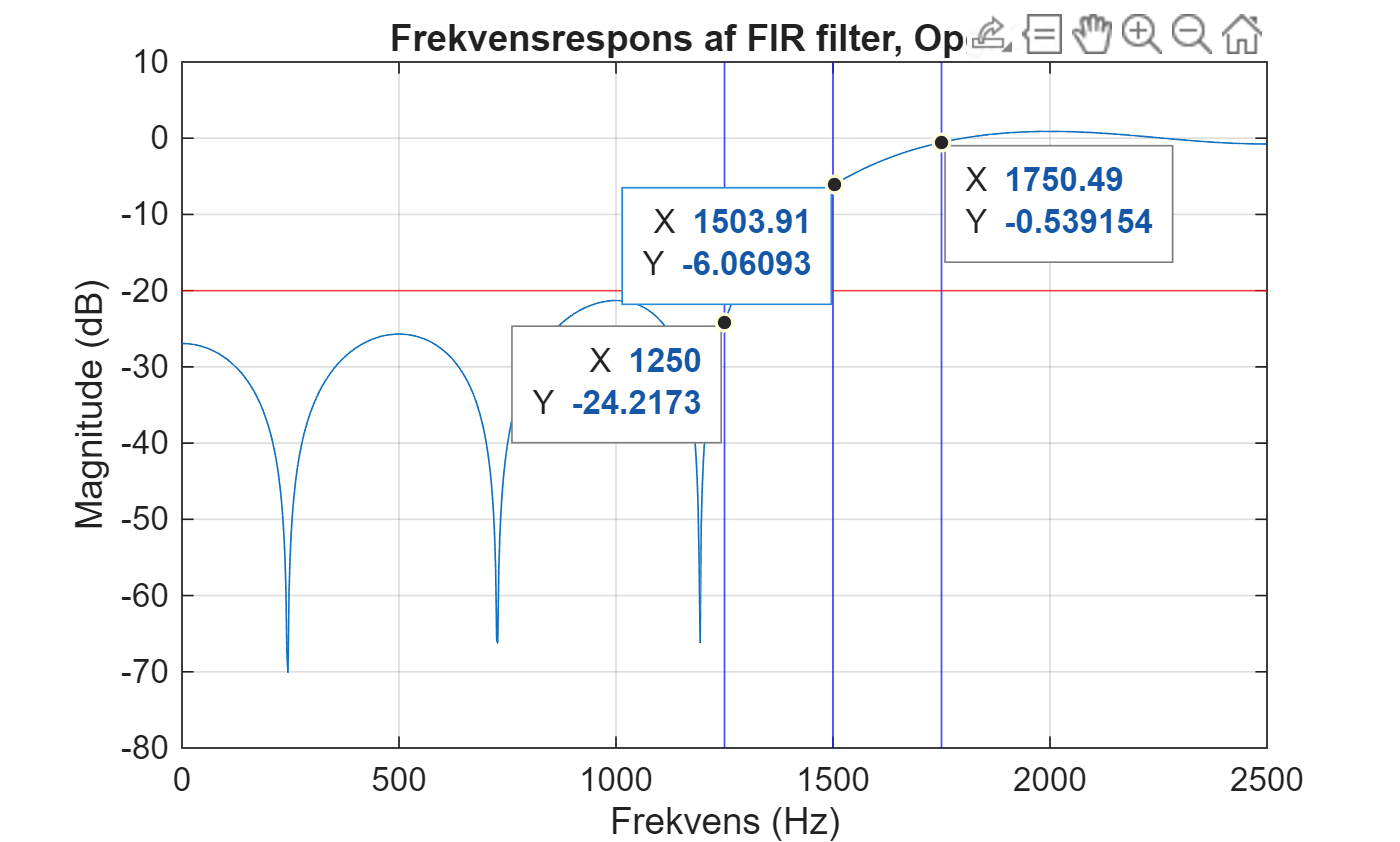


[H, f] = freqz(h, 1, 1024, F_s);

figure;
plot(f, 20*log10(abs(H)));
xlabel('Frekvens (Hz)');
ylabel('Magnitude (dB)');
xline([F_c f_s f_p], 'b');
yline([-A_sdB], 'r');
title('Frekvensrespons af FIR filter, Opg. 3-3');
grid on;

ax4 = gca;
chart4 = ax4.Children(5);
datatip(chart4,1750,-0.5392,"Location","southeast");
datatip(chart4,1504,-6.061,"Location","southwest");
datatip(chart4,1250,-24.22,"Location","southwest");

Ved plottet af frekvensresponsen, ses der at filteret opfylder kravene. Kravene var ved 1250Hz skal der være en dæmpning på 20dB. Og på plottet ses der, at ved 1250Hz er der en dæmpning på 24dB.

### 3-4

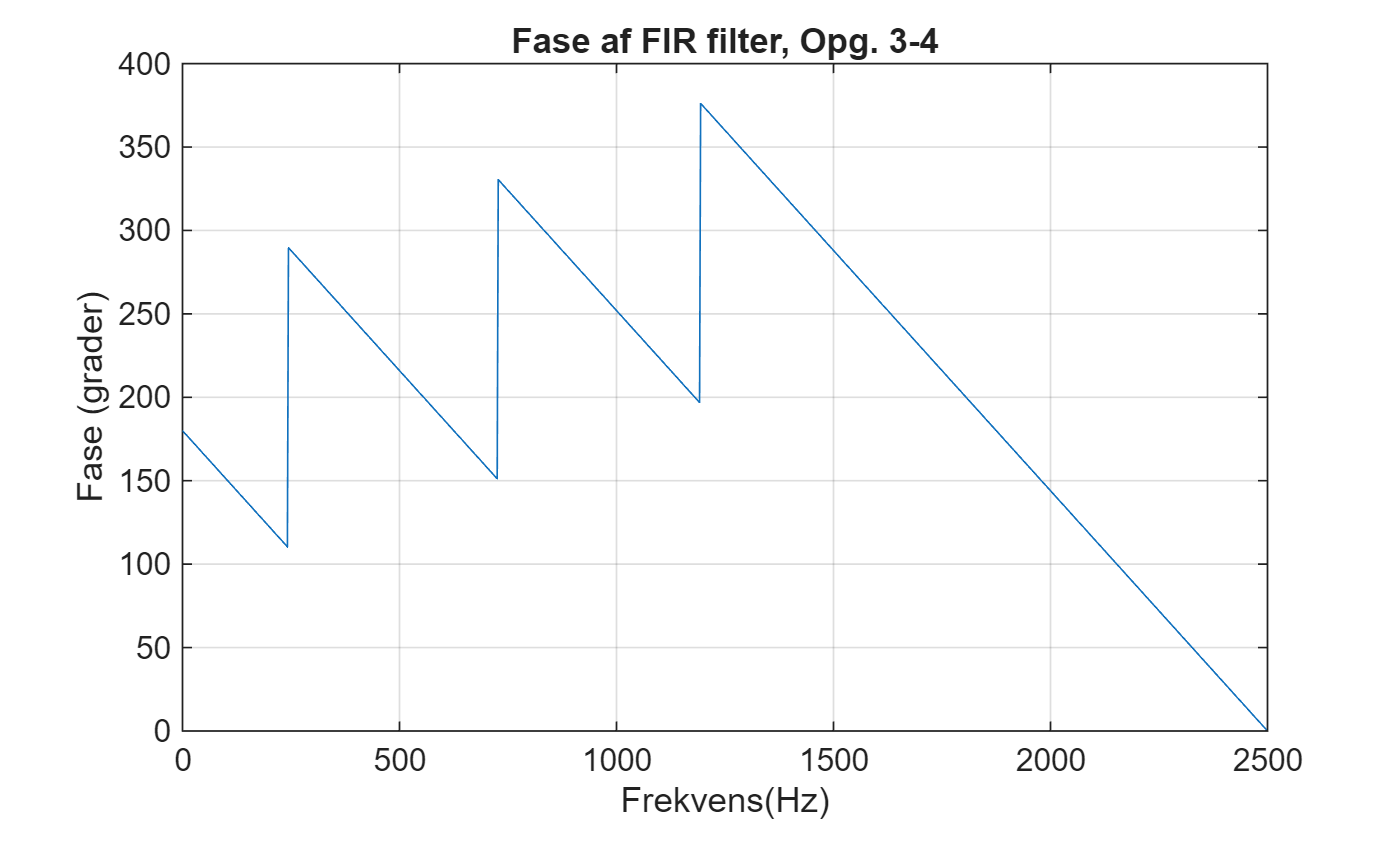

figure;
plot(f, rad2deg(unwrap(angle(H))));
xlabel('Frekvens(Hz)');
ylabel('Fase (grader)');
title('Fase af FIR filter, Opg. 3-4');
grid on;

Fasen af FIR filteret er lineært.

Baseret på impulsresponset, så er der to kriterier for at filteret er lineært. At der kun er b koefficienter, og at impulsresponset er symmetrisk.

Det kan ses på plottet for impulsresponset for FIR filteret, at den er, og vi har kun b koefficienter i transferfunktionen.

### 3-5

For at en dæmpning på 40dB skal implementeres, så er der brug for et Hanning vindue.

A_sdB = 40;

N_taps = 3.1/F_sharp

N_taps = 31

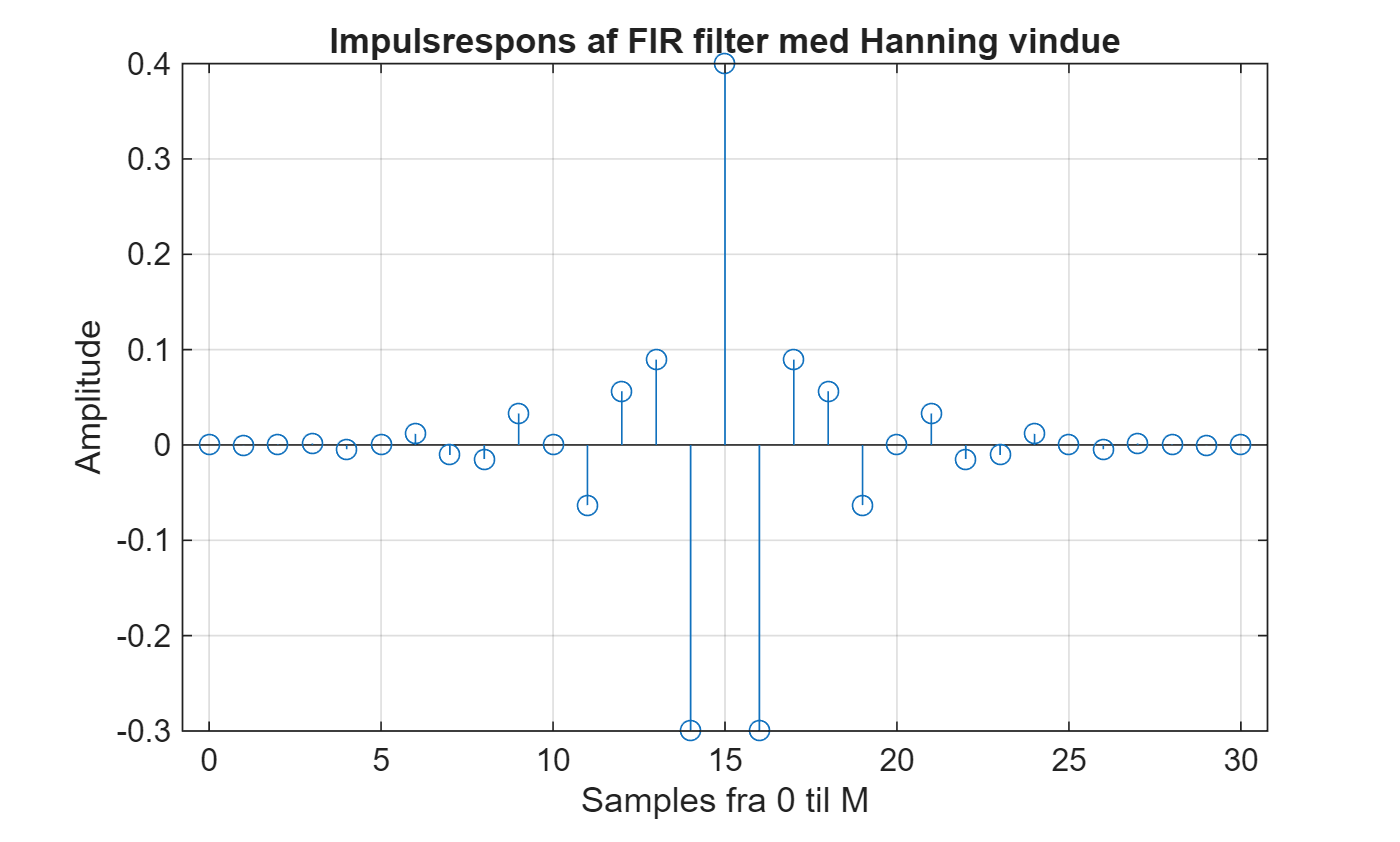

[M, K] = MK_values(N_taps);
w_hanning = FIR_window('hanning', M);
n = -K:K;
h = FIR_fourier("HP",n, omega_c);

h_w = h.*w_hanning;

figure;
stem(0:M, h_w);
xlabel('Samples fra 0 til M');
ylabel('Amplitude');
title('Impulsrespons af FIR filter med Hanning vindue');
grid on;

### 3-6

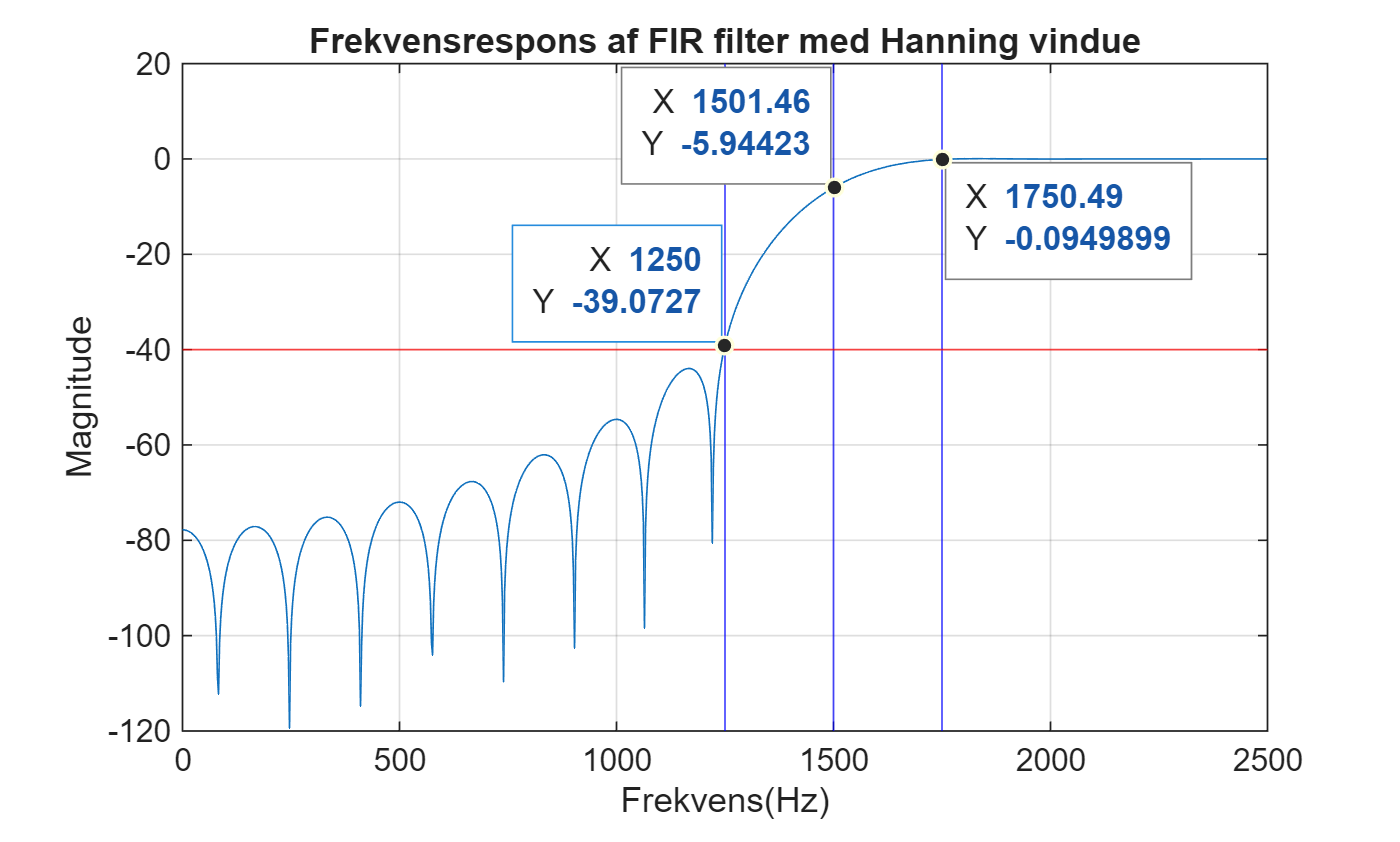

[H_w, f] = freqz(h_w, 1, 1024, F_s);

figure;
plot(f, 20*log10(abs(H_w)));
xlabel('Frekvens(Hz)');
ylabel('Magnitude');
title('Frekvensrespons af FIR filter med Hanning vindue');
xline([F_c f_p f_s], 'b');
yline([-A_sdB], 'r');
grid on;

ax5 = gca;
chart5 = ax5.Children(5);
datatip(chart5,1750,-0.09499);
datatip(chart5,1501,-5.944,"Location","northwest");
datatip(chart5,1250,-39.07,"Location","northwest");

Her ses at ved 1250Hz er der en dæmpning med 39dB, det opfylder ikke kravene for 40dB dæmpning.